# **Effet d'une arthroplastie totale inversée d'épaule sur les synergies musculaires**

**Analyse synergies sujet par sujet pour la concatéantion des 4 mouvements fonctionnelles**

Paramètres

% 1) defineParameters : définit les sujets, muscles, labels de tâches et
% l'assignation des tâches analytiques aux muscles

% 2) defineProcessingParameters : définit les paramètres de traitement EMG 
% et de détection des cycles

Traitement des données

% 1) calculateMVC : calcul la contraction maximale volontaire pour le sujet
% et les muscles selon la tâche analytic assignée à chaque muscle en prenant 
% la moyenne des cinq valeurs les plus hautes du signal RMS analytic 
% (normalisation par une tâche sous-maximale standardisée)

% 2) processFunctionalData : traite les données des mouvements fonctionnels

Traitement des artefacts

% 1) characterizeArtifacts : définis les paramètres de nettoyage des
% artefacts (propose des alternatives basées sur la moyenne, écart-type ou
% médiane du signal)

% 2) CleanEMGSignal : Nettoyage des artefacts (flagrants et extrêmes) des données

Calcul et assemblage des cycles 

% 1) detectMovementCycles : détecte les cycles en basant sur le marqueur
% RHLE (épicondyle latéral du coude)

% 2) processAndVisualizeCycle : traite et visualise les données EMG d'un cycle

% 3) mergeCloseRegions : fusionne les trois cycles pour chaque mouvement

Visualisation des cycles

% 1) visualizeCycleDetection : visualise la détection des cycles

Affichage et sauvegarde des données EMG traitées et concaténées

% 1) visualizeAllFunctionalData : visualise toutes les données fonctionnelles

% 2) saveAllData : Sauvegarde toutes les données traitées

% 3) createCycleMetadata : crée les métadonnées des cycles

% 4) printCycleSummary : Affiche un récapitulatif des cycles détectés

Traitement du mouvement fonctionnel 1: Porter les mains à la bouche
Sélectionnez 6 points (début et fin pour chaque cycle)
Cliquez sur le graphique dans cet ordre: début cycle 1, fin cycle 1, début cycle 2, fin cycle 2, etc.


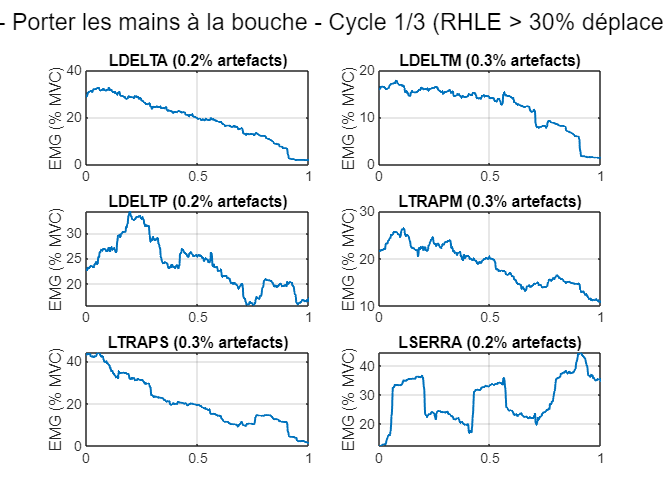

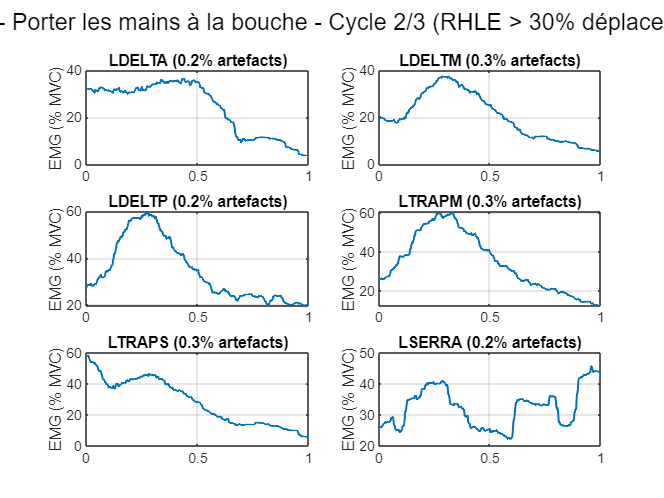

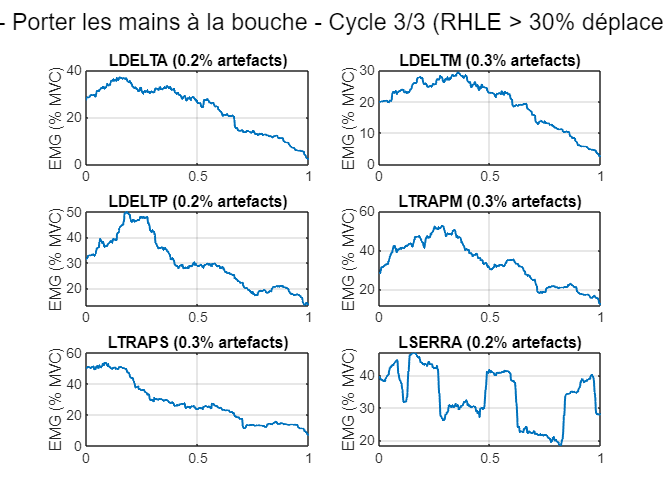

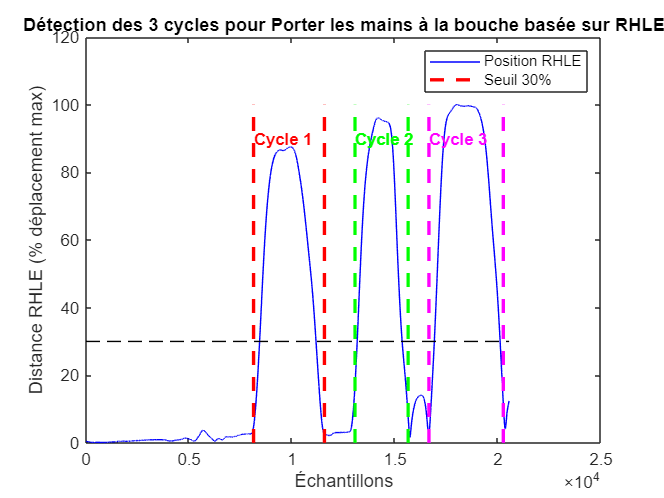

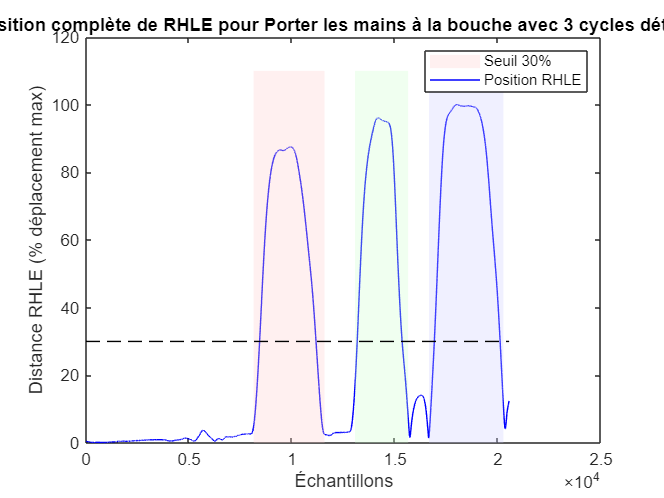

Traitement du mouvement fonctionnel 2: Toucher le haut de la tête
Sélectionnez 6 points (début et fin pour chaque cycle)
Cliquez sur le graphique dans cet ordre: début cycle 1, fin cycle 1, début cycle 2, fin cycle 2, etc.


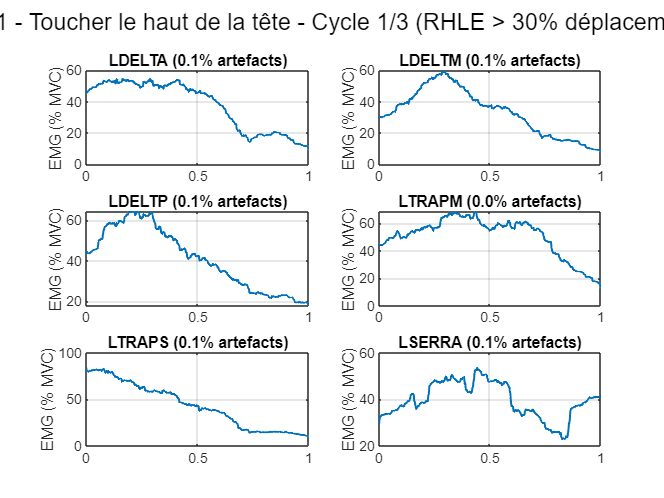

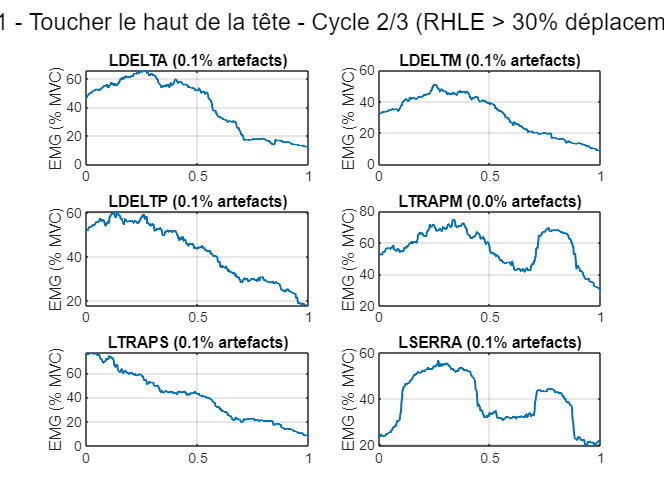

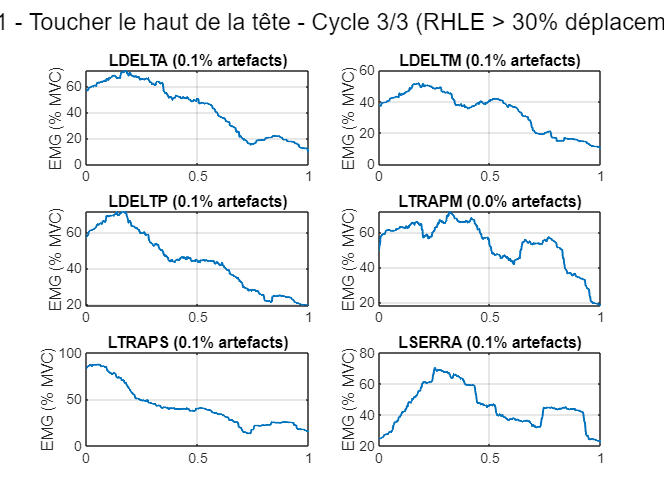

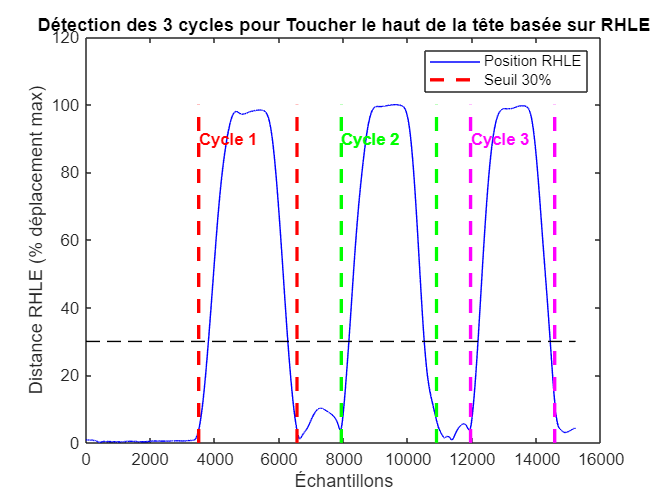

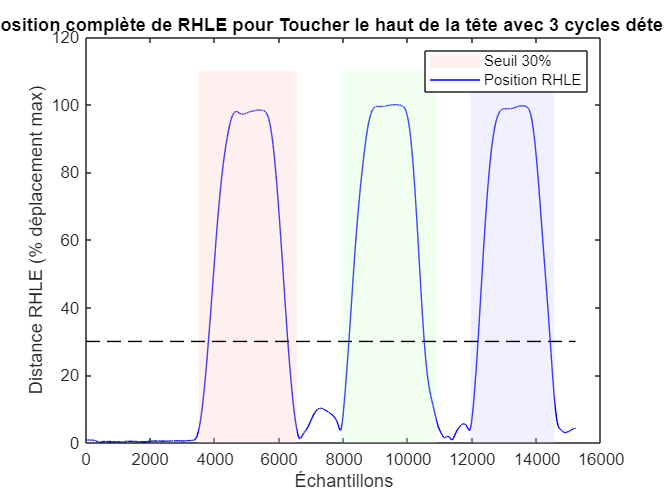

Traitement du mouvement fonctionnel 3: Porter les mains le plus haut possible au-dessus de la tête
Sélectionnez 6 points (début et fin pour chaque cycle)
Cliquez sur le graphique dans cet ordre: début cycle 1, fin cycle 1, début cycle 2, fin cycle 2, etc.


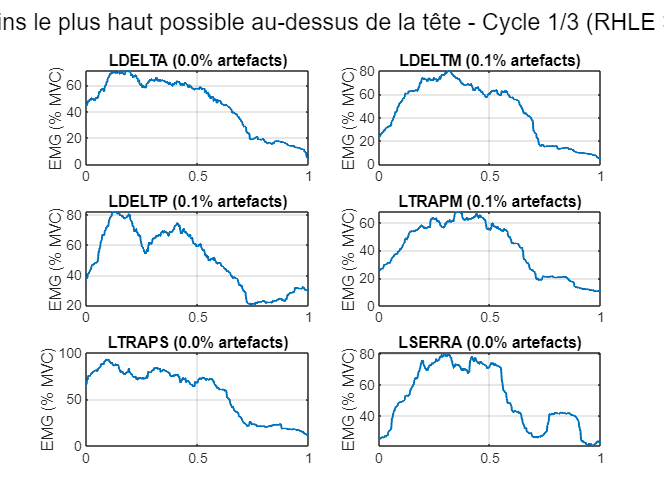

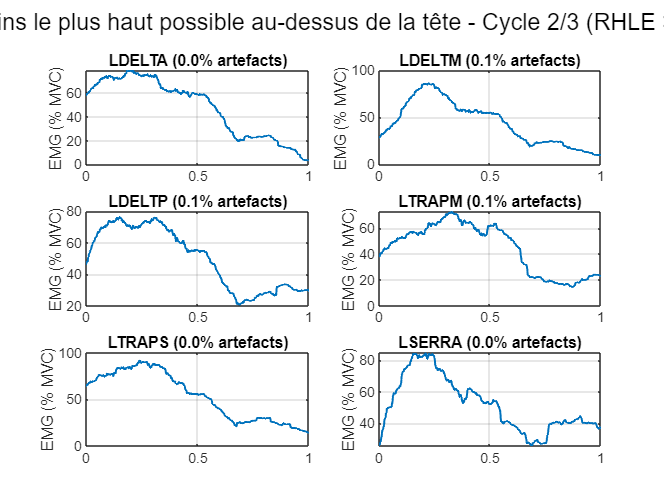

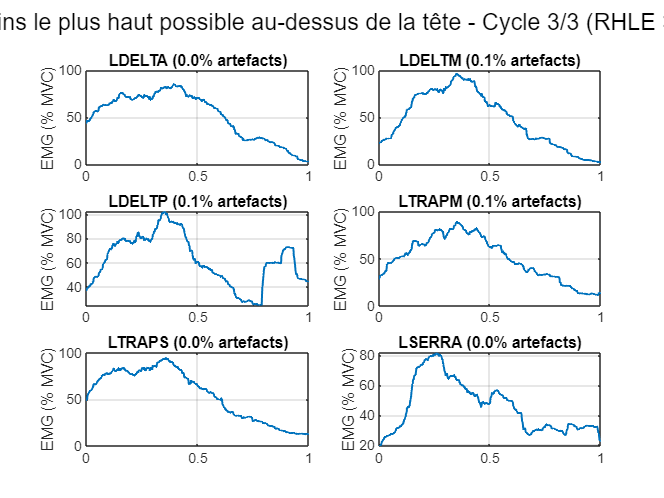

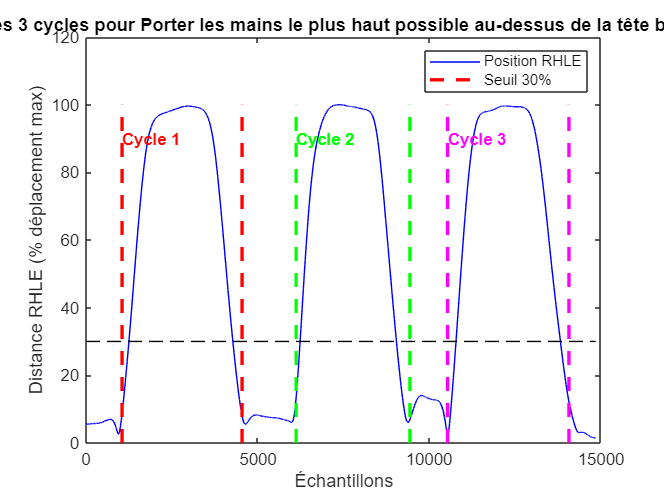

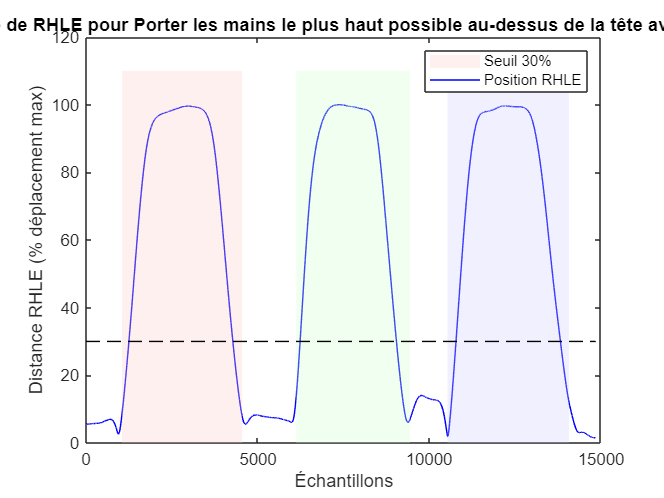

Traitement du mouvement fonctionnel 4: Porter les mains le plus haut possible le long de la colonne vertébrale
Sélectionnez 6 points (début et fin pour chaque cycle)
Cliquez sur le graphique dans cet ordre: début cycle 1, fin cycle 1, début cycle 2, fin cycle 2, etc.


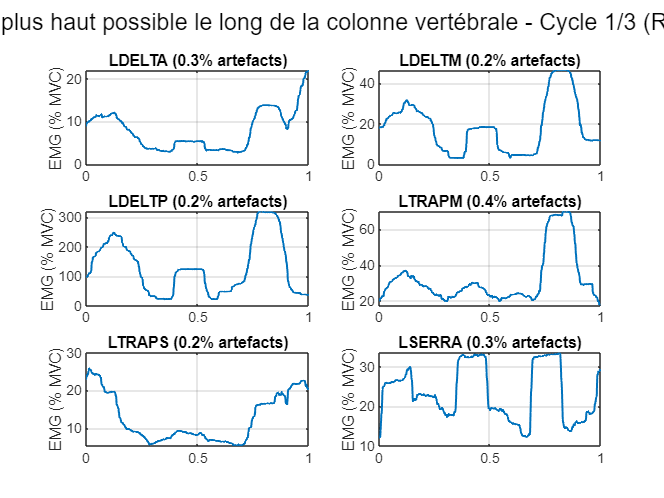

Mouvement fonctionnel 4 inversé pour le sujet S41, muscle LDELTA, cycle 1
Mouvement fonctionnel 4 inversé pour le sujet S41, muscle LDELTM, cycle 1
Mouvement fonctionnel 4 inversé pour le sujet S41, muscle LDELTP, cycle 1
Mouvement fonctionnel 4 inversé pour le sujet S41, muscle LTRAPM, cycle 1
Mouvement fonctionnel 4 inversé pour le sujet S41, muscle LTRAPS, cycle 1
Mouvement fonctionnel 4 inversé pour le sujet S41, muscle LSERRA, cycle 1


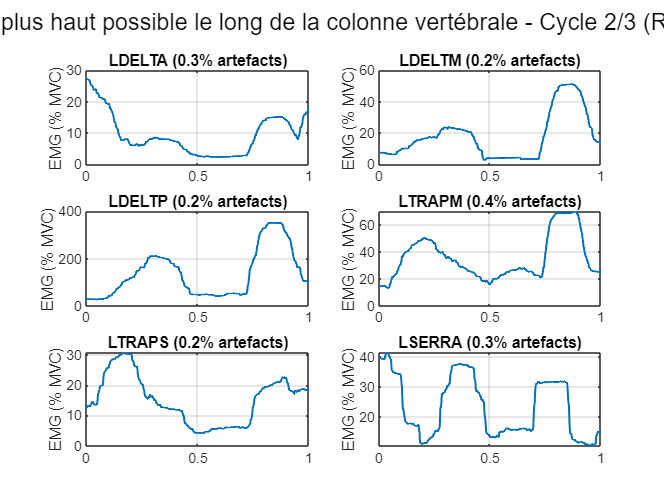

Mouvement fonctionnel 4 inversé pour le sujet S41, muscle LDELTA, cycle 2
Mouvement fonctionnel 4 inversé pour le sujet S41, muscle LDELTM, cycle 2
Mouvement fonctionnel 4 inversé pour le sujet S41, muscle LDELTP, cycle 2
Mouvement fonctionnel 4 inversé pour le sujet S41, muscle LTRAPM, cycle 2
Mouvement fonctionnel 4 inversé pour le sujet S41, muscle LTRAPS, cycle 2
Mouvement fonctionnel 4 inversé pour le sujet S41, muscle LSERRA, cycle 2


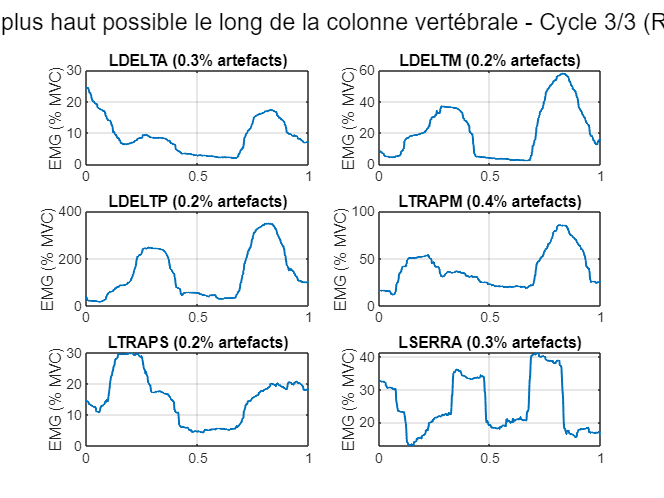

Mouvement fonctionnel 4 inversé pour le sujet S41, muscle LDELTA, cycle 3
Mouvement fonctionnel 4 inversé pour le sujet S41, muscle LDELTM, cycle 3
Mouvement fonctionnel 4 inversé pour le sujet S41, muscle LDELTP, cycle 3
Mouvement fonctionnel 4 inversé pour le sujet S41, muscle LTRAPM, cycle 3
Mouvement fonctionnel 4 inversé pour le sujet S41, muscle LTRAPS, cycle 3
Mouvement fonctionnel 4 inversé pour le sujet S41, muscle LSERRA, cycle 3


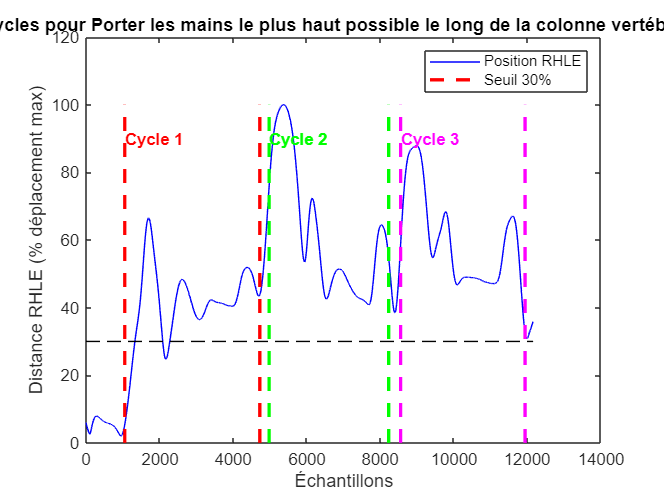

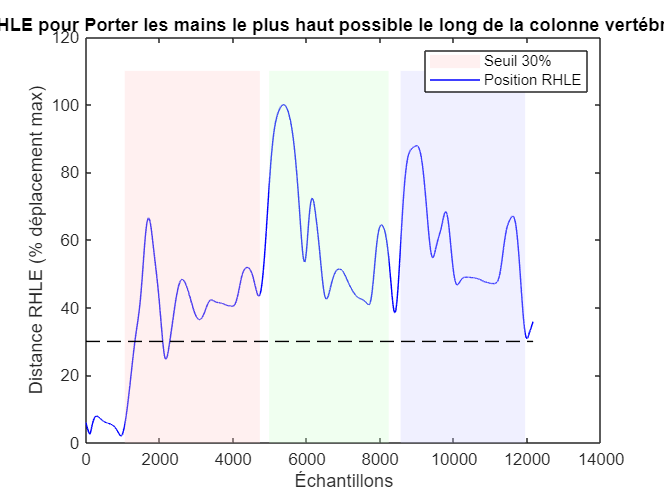

clc, clear all;
cd 'C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\Scripts\1) Synergies\Main functional'

% Ajout de la bibliothèque btk
addpath(genpath('C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\Toolboxs\btk'));
    
% Définition des paramètres
[subjects, muscles, functional_labels, analytic_labels, assigned_analytics,...
data_path] = defineParameters(3);
% 1 = Asymptomatique
% 2 = Pre_operation
% 3 = Post_operation
    
% Paramètres EMG et détection de mouvements
[b, a, rms_window, num_points, time_normalized, position_threshold_percent, min_duration, num_cycles] = defineProcessingParameters();
    
% Calcul des MVC (sous-maximaux)
mvc = calculateMVC(data_path, subjects, muscles, assigned_analytics, b, a, rms_window);

% Traitement manuel des cycles (si nécessaire)
nb_functional = length(functional_labels);
manual_selection_funcs([1, 2, 3, 4]) = true; % sélection manuelle pour les 4 mouvements

% Traitement des données fonctionnelles
[all_functional_data, num_available_cycles_per_functional] = processFunctionalData(data_path, subjects, muscles, functional_labels, b, a, rms_window, num_points, time_normalized, position_threshold_percent, min_duration, num_cycles, mvc, manual_selection_funcs);

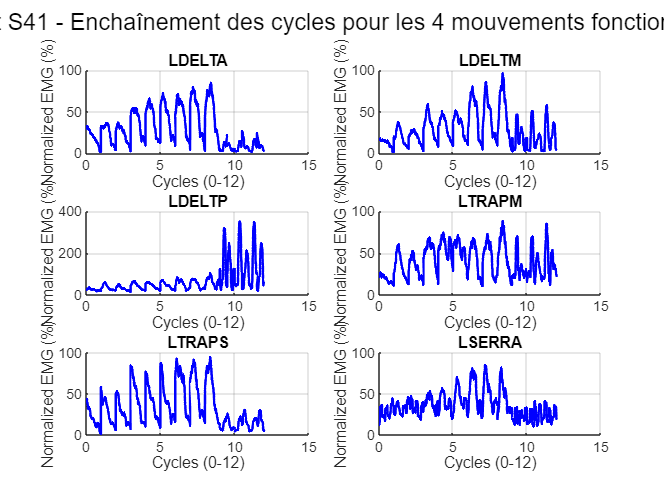

    
% Création des visualisations
visualizeAllFunctionalData(subjects, muscles, functional_labels, all_functional_data, num_available_cycles_per_functional, num_points);

    
% Sauvegarde des données (aller dans la fonction pour mettre la sauvegarde)
saveAllData(subjects, muscles, functional_labels, all_functional_data, num_available_cycles_per_functional, num_points);

Matrice de données créée avec 6 muscles et 12000 points temporels
Données sauvegardées dans le fichier: S41_all_functionals_data.mat

Récapitulatif des cycles détectés:
-----------------------------
Mouvement 1 - Porter les mains à la bouche: 3 cycles
Mouvement 2 - Toucher le haut de la tête: 3 cycles
Mouvement 3 - Porter les mains le plus haut possible au-dessus de la tête: 3 cycles
Mouvement 4 - Porter les mains le plus haut possible le long de la colonne vertébrale: 3 cycles
Total: 12 cycles
